## Hybrid Model (Parallel Molecules)

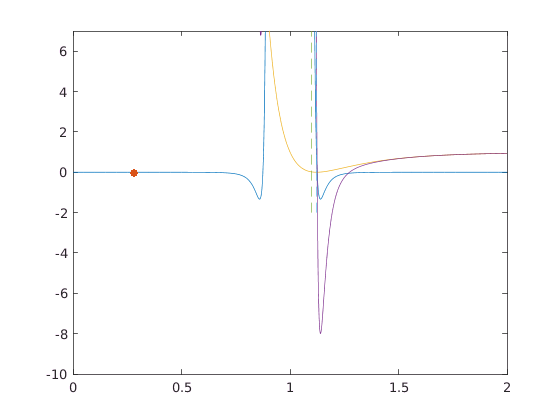

%lj stuff
eps = 8/6;
sigma = 0.125;
rcut = 1.1;
lj1 = 4 * eps * sigma^12;
lj2 = 4 * eps * sigma^6;
p1 =  [-10.852571728366474, 4.028916484460813e-08, -7.007236933439298e-12];
p2 = [-11.131928271632006, -4.0289164860161386e-08, 7.0069794804854836e-12];
r = norm(p1-p2);
rl = r - 1.0;
lj = @ (r,lj1,lj2,rcut) (1/r.^6).*(lj1./r.^6-lj2) - (1/rcut^6)*(lj1/rcut^6-lj2);
Ur = (1/rl^6)*(lj1/rl^6 - lj2) - (1/rcut^6)*(lj1/rcut^6 - lj2);
figure()
rs = 0.001:0.001:2.0;
rsl = rs - 1.0;
Urs = (1./rsl.^6).*(lj1./rsl.^6 - lj2) - (1/rcut^6)*(lj1/rcut^6 - lj2);
plot(rs,(1./rsl.^6).*(lj1./rsl.^6 - lj2) - (1/rcut^6)*(lj1/rcut^6 - lj2))
hold on
plot(r,Ur,'.','markersize',20)
ylim([-10 7])
%slj stuff
epsslj = 1;
rcutslj = 2^(1/6);
sigmaslj = 1;
delta = 0;
Urslj = lj(r,4*epsslj*sigmaslj^12,4*epsslj*sigmaslj^6,rcutslj);
ljs1 = 4 * epsslj * sigmaslj^12;
ljs2 = 4* epsslj * sigmaslj^6;
Uslj = (1./(rs-delta).^6).*(ljs1./(rs-delta).^6 - ljs2) - (1/rcutslj^6)*(ljs1/rcutslj^6 - ljs2);
plot(rs,Uslj);
plot(rs,6*Urs+Uslj);
plot([rcut rcut],[-2 7],'--')
plot([rcutslj,rcutslj],[-2 7],'--')

## KF Model (Parallel Molecules)

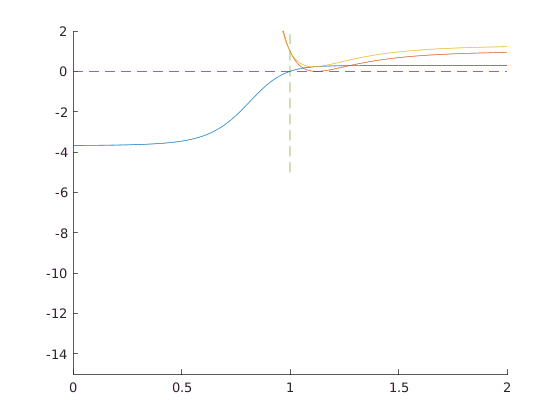

omegac = 7;
rcutkf = 1.0;
beta = 0.3;
epskf = 4;
Lp = 2;
D = 1;
Vij = (Lp+Lp)/(2*D);
rcb = rcutkf - beta;
dijs = 0.001:0.001:2.0;
edij2s = -omegac * dijs.^2 + omegac * rcb * rcb + 1;
eedij2s = exp(edij2s);
oeedij2s = 1./(1+eedij2s);
Udists = -epskf + epskf .* oeedij2s;
udist = @ (r) (-epskf + epskf / (1+ exp(-omegac * r^2 + omegac * rcb * rcb + 1)));
dij2cut = rcutkf * rcutkf;
edij2cut = -omegac * dij2cut + omegac * rcb * rcb + 1;
shift = -epskf + epskf / (1+exp(edij2cut));
figure()
hold on
plot(dijs,Udists-shift)
Uslj = (1./(dijs-delta).^6).*(ljs1./(dijs-delta).^6 - ljs2) - (1/rcutslj^6)*(ljs1/rcutslj^6 - ljs2);
plot(dijs,Uslj)
plot(dijs,Uslj+Udists - shift)
plot([0 2],[0 0],'--')
plot([rcutkf rcutkf],[-5 2],'--')
ylim([-15 2])